**Finite Difference Methods for Elliptic PDEs**

close, clear, clc
digits(128);

bx = [0, 1];
by = [0, 1];
N_x = 12;
N_y = 10;

无穷范数: 0.00149692
L2 范数: 0.000880315

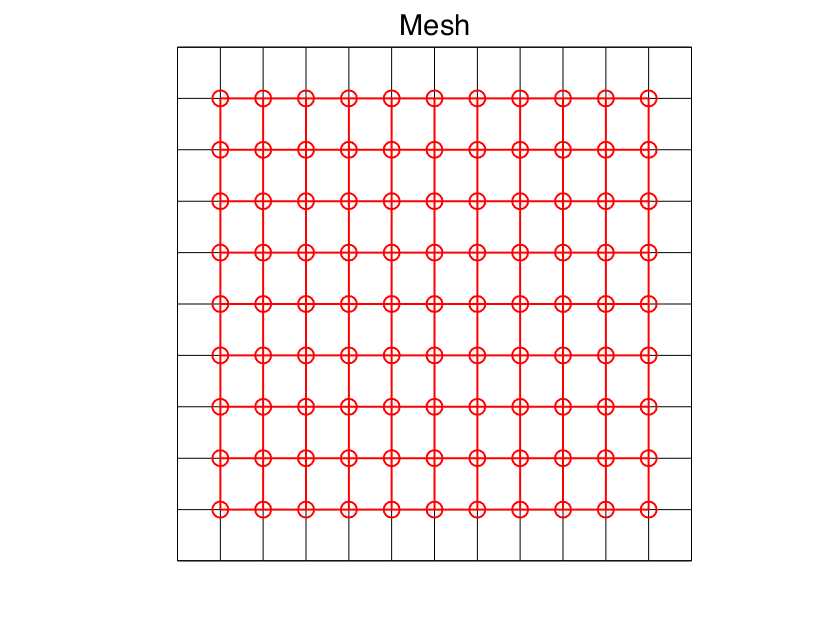

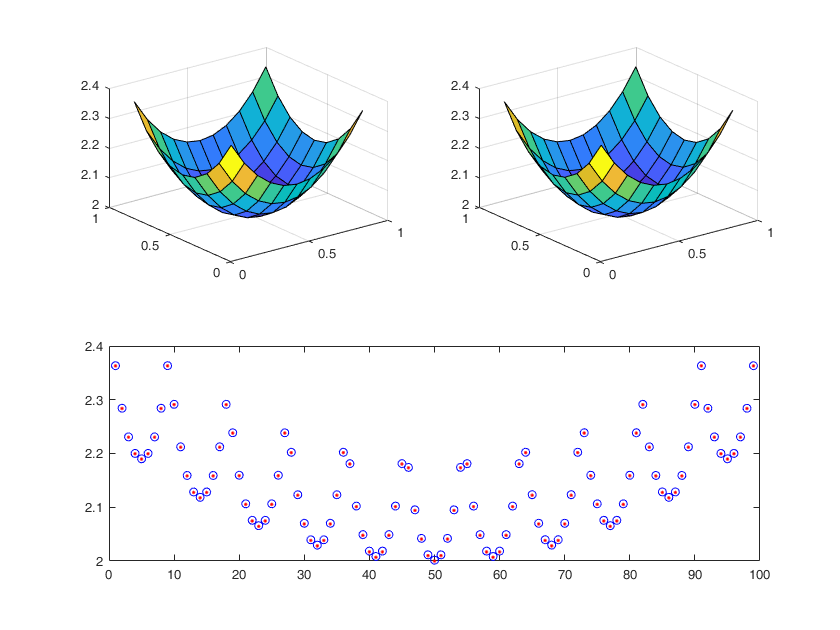

tic
Au = @(x, y)(exp((1/2 - x).^2) + exp((1/2 - y).^2));
f = @(x, y)(- 2*exp((x - 1/2)^2) - 2*exp((y - 1/2)^2) - exp((x - 1/2)^2)*(2*x - 1)^2 - exp((y - 1/2)^2)*(2*y - 1)^2);
u1 = Poisson_2D_FD_rectangle_dirichlet( bx, by, N_x, N_y, Au, f, 1 );

toc

时间已过 0.228379 秒。


无穷范数: 8.39866e-05
L2 范数: 4.66362e-05

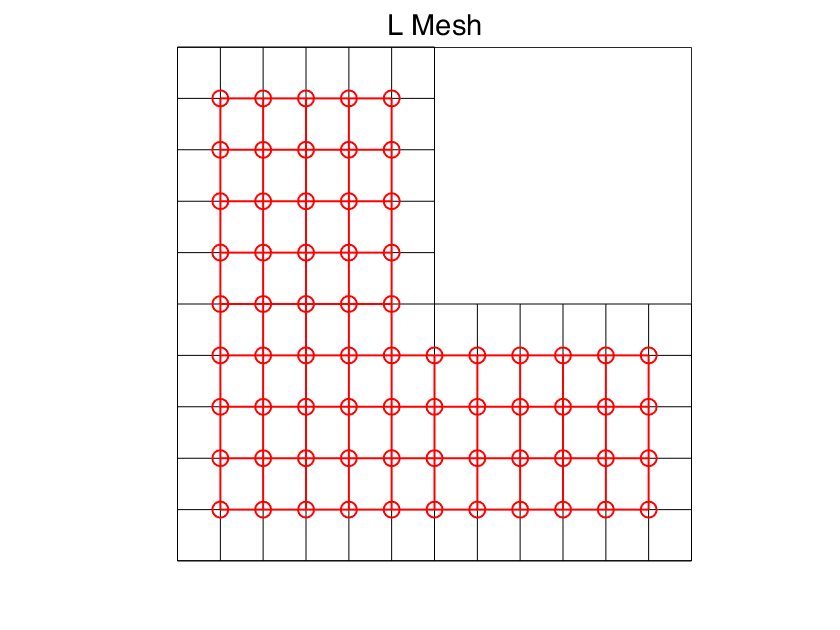

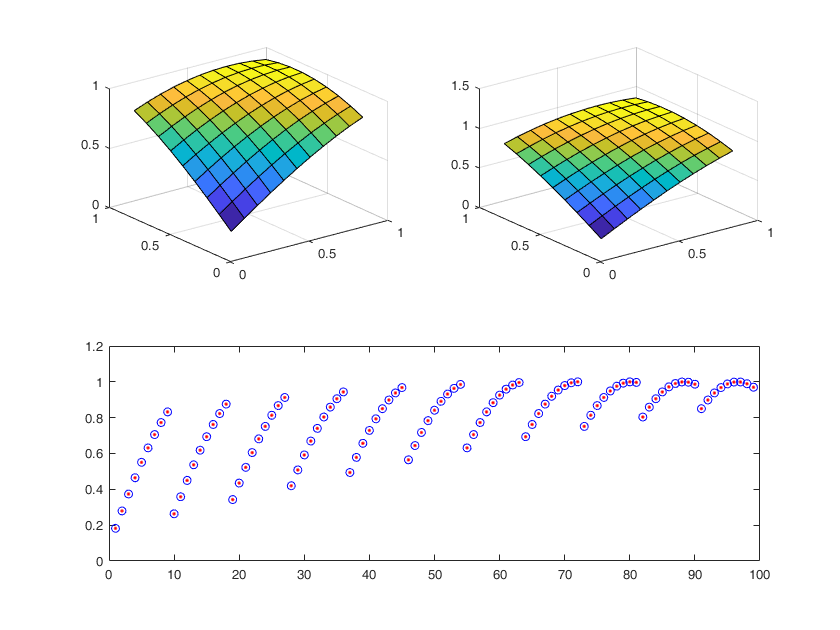

tic
Au2 = @(x, y)(sin(x+y));
f2 = @(x, y)(2*sin(x + y));
u2 = Poisson_2D_FD_rectangle_dirichlet( bx, by, N_x, N_y, Au2, f2, 2 );

toc

时间已过 0.221129 秒。


无穷范数: 1.78773e-05
L2 范数: 6.50178e-06

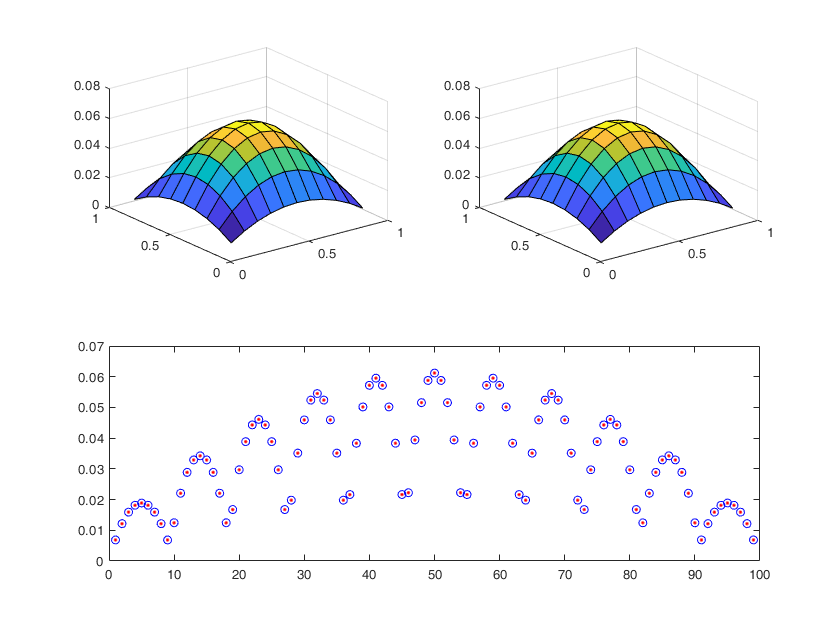

tic
Au3 = @(x, y)(sin(x.*(x-1)).*sin(y.*(y-1)));
f3 = @(x, y)(sin(x*(x - 1))*sin(y*(y - 1))*(2*x - 1)^2 - 2*cos(y*(y - 1))*sin(x*(x - 1)) - 2*cos(x*(x - 1))*sin(y*(y - 1)) + sin(x*(x - 1))*sin(y*(y - 1))*(2*y - 1)^2);
u3 = Poisson_2D_FD_rectangle_dirichlet( bx, by, N_x, N_y, Au3, f3, 1 );

toc

时间已过 0.175894 秒。
